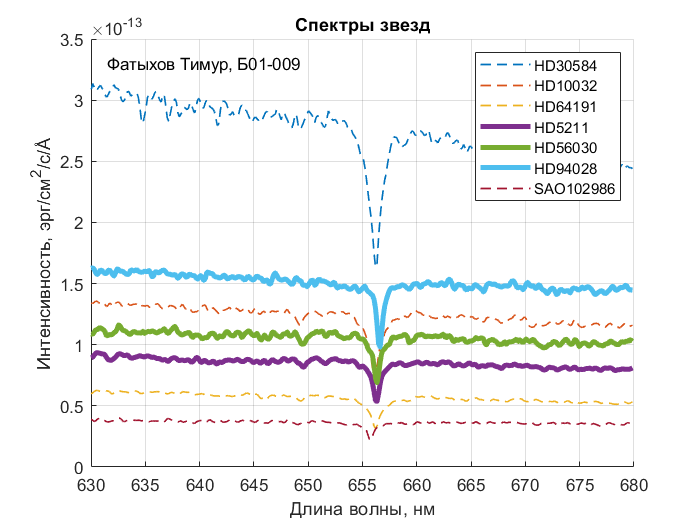

spectra     = importdata ('spectra.csv');
starNames   = importdata ('star_names.csv');
lambdaDelta = importdata ('lambda_delta.csv');
lambdaStart = importdata ('lambda_start.csv');

nObs      = size (spectra, 1);
nStars    = size (spectra, 2);
lambdaEnd = lambdaStart + (nObs - 1) * lambdaDelta;
lambda    = (lambdaStart : lambdaDelta : lambdaEnd)';

[sHa, idx] = min (spectra);

lambdaHa = lambda (idx);

Z = (lambdaHa / 656.28) - 1;
speed = Z * 299792.458;

fg1 = figure ();

hold on

for starId = 1:1:nStars
    
    if speed(starId) < 0 %синее смещение
        
        plot (lambda, spectra(:, starId), "--", 'LineWidth', 1);
    
    else                %красное смещение
        
        plot (lambda, spectra (:, starId), 'LineWidth', 3);
    
    end
    
end

text (631.5, 3.3 * 10^-13, 'Фатыхов Тимур, Б01-009');

hold off

set (fg1, 'visible', 'on');

xlabel ('Длина волны, нм');
ylabel (['Интенсивность, эрг/см^2/с/', char(197)]);
title  ('Спектры звезд');

legend (starNames);
grid   on

saveas (fg1, 'allSpectra.png');


starIndexArr = 1:1:nStars

starIndexArr =      1     2     3     4     5     6     7


movaway = starNames( starIndexArr (speed (starIndexArr) > 0) ) 

movaway = 3×1 cell array
    {'HD5211' }
    {'HD56030'}
    {'HD94028'}
